% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear
% Please be advised this section is another experiment.
q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter


xmax = 1;
xmin = -xmax;
M = 11; % Total number of bins in [-xmax,xmax]
x_bin_size = (xmax-xmin)/M;
x_grid = linspace(xmin+0.5*x_bin_size,xmax-0.5*x_bin_size,M);

x_P = ones(1,M)/M; % Uniform distribution for testing

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2603   -0.0950   -0.2166   -0.0134   -0.0023   -0.1943   -0.0103         0   -0.1153   -0.0761   -0.1952


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8108    0.7446    0.6855    0.6194    0.5401    0.4410    0.5401    0.6194    0.6855    0.7446    0.8108


filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_pMatrix.csv', axRatio,xmax,eps,delta);

filename = 'uniform_axRatio4_xmax1.0_eps2.0_delta0.0_pMatrix.csv'

writematrix(pMatrix,filename,'Delimiter','comma')
filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_xGrid.csv', axRatio,xmax,eps,delta);

filename = 'uniform_axRatio4_xmax1.0_eps2.0_delta0.0_xGrid.csv'

writematrix(x_grid,filename,'Delimiter','comma')
filename = sprintf('uniform_axRatio%d_xmax%.1f_eps%.1f_delta%.1f_aGrid.csv', axRatio,xmax,eps,delta);

filename = 'uniform_axRatio4_xmax1.0_eps2.0_delta0.0_aGrid.csv'

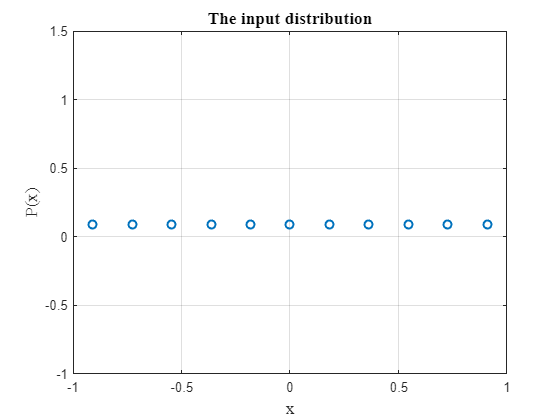

writematrix(a_grid,filename,'Delimiter','comma')
% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

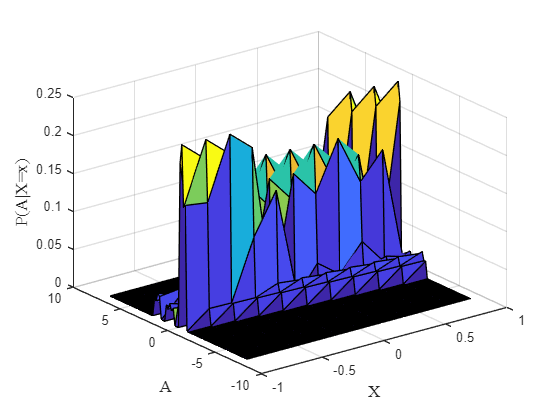

figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');